Trun = 30

Trun = 30

N_samples = Trun*Fs; %measurement size per duration(samples)
T_terminate = 5;

Exercise = "ProtoLab_setup_45_2110";
Measurement = "Setpoint_11s_13p5Hz_noI";
SampleFreq = "fs_" + Fs + "_Hz";

ModelName = "Hardware_Performance_run";
[success, e,y,r] = StartPerformanceMeasurement(p,N_samples,T_terminate,ModelName);

Starting the measurement, should take 30 seconds to collect 120000 Samples.
Measurement finished.
Retrieving measurement file(s).
Files retrieved.


if(~success)
    error("No measurement made!");
end
e_max = max(e)

e_max = 0.0094

e_rms = rms_error(e)

e_rms = 0.0030

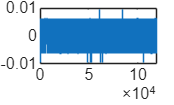


figure; stairs(e);

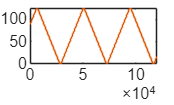

figure; stairs(y); hold on; stairs(r);



Path = "PerformanceMeasurements/"  ...
        + Exercise ...
        + "/" + SampleFreq;

measurementName = Measurement + "_T" + Trun + "_S" + N_samples;
saveMeasurement(...
struct("runtime", Trun, "fs", Fs, "samples", N_samples), ...%settings    
struct("r", r,"e",e,"y",y), ... %signals
struct([]),...
Path + '/PerformanceData/'+ measurementName);


function e_rms = rms_error(e)
%RMS_ERROR  Compute RMS value of an error signal.
%
%   e_rms = RMS_ERROR(e)
%
%   Inputs:
%       e - error signal vector (difference between ref and measurement)
%
%   Output:
%       e_rms - root mean square error
%
%   Example:
%       e = [0.1, -0.2, 0.05, 0.15];
%       e_rms = rms_error(e)

    % Ensure it's a vector
    e = e(:);

    % Compute discrete-time RMS
    e_rms = sqrt(mean(e.^2));
end
